# TP2: Classification de chiffres écrits à la main

On considère un jeu de données USPS (US Postal Service), contenant des images de chiffres écrits à la main. On peut voir des exemples de telles images sur la figure ci-dessous. L’objectif est d’entrainer un classifieur SVM dans le cadre d'une tâche de classification supervisée, précédée par une étape de réduction de dimension utilisant la SVD (ACP).

                                                                    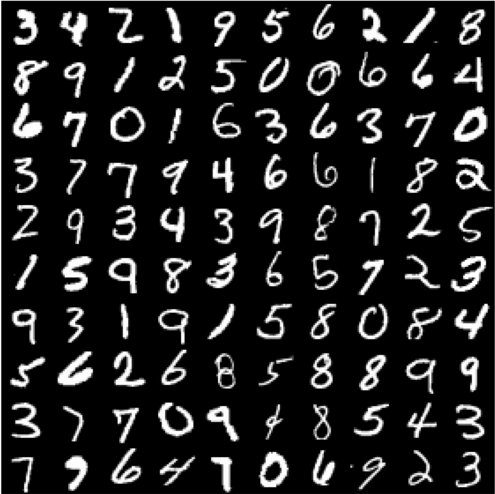

## 1. Jeu de données USPS

Le jeu de données se trouve dans le fichier `usps_all.mat` et est représenté par un tenseur `data` d'ordre $3$. Les dimensions du tenseur sont $256 \times 1100 \times 10$. 

load("usps_all.mat"); % charge data
data = double(data);

Chaque colonne `data(:,j,k)` est la vectorisation d'une image $16\times 16$, pour laquelle l'indice `k` correspond à une classe (de $0$ à $9$) et l'indice `j` correspond à un échantillon. Ainsi, la première dimension correspond aux pixels, la deuxième aux chiffres, et la troisième aux classes, comme montré dans la figure ci-dessous. L'ordre des classes est $'1'$, $'2'$, $\ldots$, $'9'$, $'0'$.

- Afficher quelques exemples des images d'entraînement, dans les classes $7$ et $9$ par exemple, à l'aide de `imagesc`.

colormap(gray);
% Insérer le code ici

- En apprentissage automatique, il est d'usage de séparer le jeu de données en deux parties: une partie servant à l'entraînement du modèle ("training"), l'autre à sa validation. Diviser le jeu de données en deux tenseurs `T` et `V`, en sélectionnant des sous-tenseurs de `data` selon la deuxième dimension (échantillons). Les indices `ind_train` et `ind_valid` correspondant à chaque sous-tenseurs sont donnés dans le fichier `usps_partition.mat`.

load("usps_partition.mat"); % charge ind_train et ind_valid
% Insérer le code ici
T = data(:,ind_train,:);
V = data(:,ind_valid,:);

## 2. Analyse en composantes principales (ACP)

- Pour le tenseur des données d'entraînement `T`, calculer le dépliement du tenseur `T` selon le mode $1$ (une matrice avec 256 lignes) à l'aide de la commande `reshape`, et trouver la matrice `U` des $10$ premiers vecteurs singuliers gauches.

% Insérer le code ici
T1 = reshape(T,256,[]);
[U,S,~] = svd(T1);
U = U(:,1:10);

- Replier chaque vecteur singulier en une matrice $16\times 16$ à l'aide de `reshape` et les afficher avec `imagesc`.

% Insérer le code ici

Dans la suite, nous allons entraîner un classifieur SVM sur deux des 10 classes (les chiffres $7$ et $9$).

- Extraire de `T` les données des deux classes 7 et 9 (avec la commande `T(:,:,?)), et décomposer ces données en une matrice Xt(chiffre,pixel)` de 256 colonnes, et un vecteur `yt(classe)` de labels.

% Insérer le code ici
Xt = [T(:,:,7)';T(:,:,9)'];
yt = kron([7;9],ones(size(ind_train)));

- Décomposer de même les données de validation en matrice `Xv` et vecteur `yv.`

% Insérer le code ici

- Les colonnes de la matrice `U `calculée précédemment engendrent un espace vectoriel de faible dimension (ici 10), qui est une (bonne) approximation de l'image de `X.` L'ACP consiste à projeter nos données sur cet espace de dimension réduite.

Xt_ACP = Xt*U; % projection sur l'espace engendré par les 10 premiers vecteur singuliers

## 3. Classification SVM

Le classifieur SVM de Matlab est `fitcsvm`. Cette fonction prend plusieurs options (consulter son aide), notamment:

- 'BoxConstraint' : si cette option est fixée sur `inf`, le classifieur utilisera une marge dure. Pour toute autre valeur strictement positive, la marge sera souple (la valeur par défaut est 1)

- 'KernelFunction': le noyau utilisé le cas échéant (par exemple 'polynomial', 'gaussian', etc...)

- 'KernelScale' : dans le cas d'un noyau gaussien, ce paramètre correspond à l'écart-type (par défault, 1)

- 'Verbose' : affiche ou non les informations liées au classifieur pendant l'optimisation (par défault, 1)

- Retrouver ces différents paramètres dans l'aide de `fitcsvm`.

- Entraîner un classifieur SVM à marge souple et à noyau gaussien sur les données projetées `X_ACP. `Attention: on utilisera le paramètre `..., `'`Standardize', true, ... `pour normaliser les données.

%s = fitcsvm %(Insérer le code ici);
s = fitcsvm(X_ACP,y,'KernelFunction','gaussian','Standardize',true);

Une fois le classifieur entraîné, les valeurs de labels prédites à partir des données `X_ACP` se calculent avec la commande `predict`.

labels = predict(s,X_ACP);

Dans le cas de deux classes, disons par exemple 1 et 0, la commande Matlab `confusionmat` retourne la matrice de confusion associée aux prédictions, c'est-à-dire la matrice $\pmatrix{\mathrm{TP} & \mathrm{FN} \cr \mathrm{FP} & \mathrm{TN}}$ avec

- TP: nombre de bonnes prédictions de la classe 1 ("true positive")

- FP: nombre de mauvaises prédictions de la classe 1 ("false positive")

- FN: nombre de mauvaises prédictions de la classe 0  ("false negative")

- TN: nombre de bonnes prédictions de la classe 0 ("true negative").

Une mesure possible du taux d'erreur est donné par $\frac{FP+FN}{n}$ où $n$ est le nombre d'échantillons. 

- Calculer le taux d'erreur de classification sur les données d'entraînement.

% Insérer le code ici

- Réduire la dimension des données de validation avec la même matrice `U` qui a été utilisée pour les données d'apprentissage. Calculer les prédictions est le taux d'erreurs de classification.

% Insérer le code ici

## 4. Réglages des hyperparamètres

- Répéter les codes précédents pour différentes valeurs du paramètre `'KernelScale' dans l'intervalle [0;20]`. Tracer les courbes des erreurs d'apprentissage et de validation correspondant. Quelle est une bonne valeur de ce paramètre?

sigma_list = 0.5:0.5:20;
% Insérer le code ici
for i=1:length(sigma_list)
    % Insérer le code ici
end
% Insérer le code ici (plot)

-  Une façon courante et pratique de régler les hyperparamètres (comme `'KernelScale'`) est d'utiliser la méthode de validation croisée. Cette méthode n'utilise que les données d'apprentissage, en les sous-divisant d'une manière astucieuse en sous-ensembles d'entraînement et de validation. On peut optimiser le paramètre `'KernelScale'` de la façon suivante:

s_opt = fitcsvm(Xt,yt,'Verbose',1,'Standardize',true,'KernelFunction','gaussian','KernelScale',1,'OptimizeHyperparameters','KernelScale');
sigma_opt = s_opt.KernelParameters.Scale;

- Comparez les résultats (paramètre optimal, taux d'erreur) avec l'erreur de validation obtenue à l'étape précédente.

% Insérer le code ici

## 5. Pour aller plus loin

- Répétez la procédure pour deux autres classes (chiffres 6 et 8). Est-il plus difficile de séparer ces classes? La courbe d'erreur de validation est-elle différente de la précédente?

- Prenez deux photos (noir et blanc, carré) avec votre smartphone, représentant les deux classes (6 et 8), ou utilisez les photos fournies dans les fichiers du tp. Classifiez-les après les étapes de pré-traitement suivantes:

- Recadrage

- Conversion en négatif (blanc sur fond noir)

- Correction du contraste -- il faut normaliser les données de telle façon que les valeurs minimales et maximales deviennent 0 et 255: $f_{i,j} = \frac{f_{i,j}-f_{\min}}{f_{\max}-f_{\min}} \cdot 255$

- Redimensionnement à l'aide de la fonction `imresize`.

% Insére le code ici

## 6. Pour aller encore plus loin: classification multi-classes

Cette partie de TP est proposée uniquement pour ceux qui auraient déjà tout fait.

Il y a deux stratégies principales pour entraîner un classifieur multi-classe (avec M classes) à partir des outils de classification bi-classes que nous avons vues:

**1. *****One-vs-one***: on entraine des classifieurs SVM bi-classes pour chacune des $M(M-1)/2$ paires de classes. Par exemple : ’1’ vs. ’2’, ’1’ vs. ’3’, ..., ’1’ vs. ’0’, ’2’ vs.’3’, ..., ’2’ vs. ’0’, ... etc. Pour trouver une prediction, on évalue ensuite tous les classifieurs sur un nouvel echantillon, et on choisit la classe qui ressort le plus souvent. Par exemple :

-  ’1’ vs. ’2’ : ’1’

-  ’1’ vs. ’3’ : ’1’

-  ’2’ vs. ’3’ : ’3’

⇒ la classe ’1’ est choisie

***2. One-vs-all:*** On entraine M classifieurs pour la classification binaire :

- ’1’ vs. ’2’,’3’,...,’0'

- ’2’ vs. ’1’,’3’,...,’0’

- $\vdots$

- ’0’ vs. ’2’,’3’,...,’9’

- Implémenter une des deux stratégies pour le jeu de données USPS. Calculer la matrice de confusion et le taux d'erreur.